%Experiment 1:
clear
clf
load('Experiment 1/Vin.mat')
load('Experiment 1/Iout.mat')

[first, last, mmax, bmax, Nmax]=linefit(Vin, Iout, 10e-6)

first = 8

last = 21

mmax = 1.0067e-04

bmax = -2.6505e-07

Nmax = 14

resistance=1/mmax

resistance = 9.9332e+03

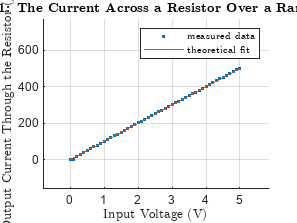


hold on
grid on
title("\textbf{Experiment 1: The Current Across a Resistor Over a Range of Voltages}", "interpreter", "latex")
xlabel("Input Voltage (V)", "interpreter", "latex")
ylabel("Output Current Through the Resistor ($\mu$A)", "interpreter", "latex")

plot(Vin,Iout*10^6,".")

vin=0:0.1:5;
plot(vin,vin/10000*10^6)

legend("measured data","theoretical fit", "interpreter", "latex")
hold off

%Experiment 2:
clear
clf
load('Experiment 2/Vin.mat')
load('Experiment 2/Vout.mat')

[first, last, mmax, bmax, Nmax]=linefit(Vin, Vout, 10e-6)

first = 22

last = 42

mmax = 0.5000

bmax = 0.0218

Nmax = 21

Divider=mmax

Divider = 0.5000

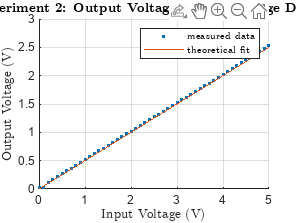


hold on
grid on
title("\textbf{Experiment 2: Output Voltage from a Voltage Divider}", "interpreter", "latex")
xlabel("Input Voltage (V)", "interpreter", "latex")
ylabel("Output Voltage (V)", "interpreter", "latex")

plot(Vin,Vout,".")

tvin=0:0.1:5;
plot(tvin,1/2*tvin)

legend("measured data","theoretical fit", "interpreter", "latex")
hold off

%Experiment 3:
clear
clf
%Sorry for absolute path
load('Experiment 3\lin.mat')
load('Experiment 3\Iout.mat')

[first, last, mmax, bmax, Nmax]=linefit(Iin, Iout, 10e-6)

first = 28

last = 42

mmax = -0.5030

bmax = -4.8300e-06

Nmax = 15

Divider=mmax

Divider = -0.5030

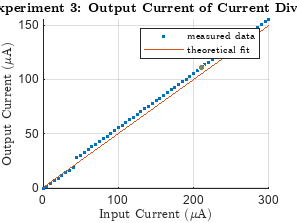


hold on
grid on
title("\textbf{Experiment 3: Output Current of Current Divider}", "interpreter", "latex")
xlabel("Input Current ($\mu$A)", "interpreter", "latex")
ylabel("Output Current ($\mu$A)", "interpreter", "latex")

plot(Iin*10^6,-Iout*10^6,".")
tIin=0:0.0001:0.0003;

plot(tIin*10^6,1/2*tIin*10^6)

legend("measured data","theoretical fit", "interpreter", "latex")
hold off

%Experiment 4:
clear
clf
%Sorry for absolute path
load('Experiment 4\All_Data.mat')

%[first, last, mmax, bmax, Nmax]=linefit(Iin, Iout, 10e-6)
%Divider=mmax

positions = [1 2 3 4];
data_V5 = [-Iout5v1(end)*10^6 -Iout5v2(end)*10^6 -Iout5v3(end)*10^6 -Iout5v4(end)*10^6];
data_V3 = [-Iout3v1(end)*10^6 -Iout3v2(end)*10^6 -Iout3v3(end)*10^6 -Iout3v4(end)*10^6];
theory_V3 = 3 * (1./(2.^positions)) * (1/(2*10000)) * 10^6

theory_V3 =    75.0000   37.5000   18.7500    9.3750


theory_V5 = 5 * (1./(2.^positions)) * (1/(2*10000)) * 10^6

theory_V5 =   125.0000   62.5000   31.2500   15.6250


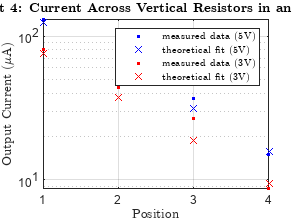


semilogy(positions, data_V5,"b.")
hold on
semilogy(positions, theory_V5, "bx")
semilogy(positions, data_V3,"r.")
semilogy(positions, theory_V3, "rx")
title("\textbf{Experiment 4: Current Across Vertical Resistors in an R-2R Ladder}", "interpreter", "latex")
xlabel("Position", "interpreter", "latex")
ylabel("Output Current ($\mu$A)", "interpreter", "latex")
grid on
legend("measured data (5V)","theoretical fit (5V)", "measured data (3V)","theoretical fit (3V)", "interpreter", "latex")
%tIin=0:0.0001:0.0003;
%plot(tIin*10^6,1/2*tIin*10^6)
hold off